# Comparative analysis on Synthetic Data


close all
clear

tic

plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

input.nCells = 135;
input.nAlgos = 8;

% Synthetic Dataset Details
input.gDate = 20210824; %generation date
input.gRun = 1; %generation run number
input.nDatasets = 333;

% Consolidated Analysis Details
input.cDate = 20210918; %consolidation date
input.cRun = 1; %consolidation run number

workingOnServer = 0;
diaryOn         = 0;


## Directory config


if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/dataGenDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/dataGenDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end


## ROC Curves for all methods

input.plotOptimalPoint = 0;

input.nCells = 135;
input.nMethods = 7;

% Synthetic Dataset Details
input.gDate = 20210824; %generation date
input.gRun = 1; %generation run number
input.nDatasets = 333;

% Consolidated Analysis Details
input.cDate = 20210918; %consolidation date
input.cRun = 1; %consolidation run number

workingOnServer = 0;
diaryOn         = 0;

## Load Synthetic Data

disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


% gDate = 20210628; %generation date
% gRun = 1; %generation run number
% nDatasets = 80;
synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!


## Load Analysis Results

disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 1;
input.saveFolder = saveFolder;
[Y, X] = developConfusionMatrix(input, sdo_batch, cData);

Creating Look Up Table ...
... done!



%% TP, FN, FP, TN
nCases = length(Y);

%Preallocation
allTP = zeros(nCases, input.nAlgos);
allTN = zeros(nCases, input.nAlgos);
allFP = zeros(nCases, input.nAlgos);
allFN = zeros(nCases, input.nAlgos);
TPR = zeros(input.nAlgos, 1); %Sensitivity
FPR = zeros(input.nAlgos, 1); %Fall-out or False Positive Rate
TNR = zeros(input.nAlgos, 1); %Specificity
FNR = zeros(input.nAlgos, 1); %Miss Rate
PPV = zeros(input.nAlgos, 1); %Positive Predictive Value
NPV = zeros(input.nAlgos, 1); %Negative Predictive Value
FDR = zeros(input.nAlgos, 1); %False Discovery Rate
FOR = zeros(input.nAlgos, 1); %Flase Omission Rate
PT = zeros(input.nAlgos, 1); %Prevalence Threshold
TS = zeros(input.nAlgos, 1); %Threat Score or Critical Success Index (CSI)
ACC = zeros(input.nAlgos, 1); %Accuracy
BA = zeros(input.nAlgos, 1); %Balanced Accuracy

results1 = zeros(input.nAlgos, 4);
results2 = zeros(input.nAlgos, 4);

for algo = 1:input.nAlgos
    for myCase = 1:nCases
        if Y(myCase) %Positive Cases
            if X(myCase, algo)
                allTP(myCase, algo) = 1;
            else
                allFN(myCase, algo) = 1;
            end
        else %Negative Casees
            if X(myCase, algo)
                allFP(myCase, algo) = 1;
            else
                allTN(myCase, algo) = 1;
            end
        end
    end
    
    TP = sum(allTP(:, algo));
    FN = sum(allFN(:, algo));
    FP = sum(allFP(:, algo));
    TN = sum(allTN(:, algo));
    
    TPR(algo) = TP/(TP + FN);
    FPR(algo) = FP/(FP + TN);
    TNR(algo) = TN/(TN + FP);
    FNR(algo) = FN/(FN + TP);
    
    PPV(algo) = TP/(TP + FP);
    NPV(algo) = TN/(TN + FN);
    FDR(algo) = FP/(FP + TP);
    FOR(algo) = FN/(FN + TN);
    
    PT(algo) = (sqrt(TPR(algo)*(-TNR(algo) +1)) + TNR(algo) - 1)/(TPR(algo) + TNR(algo) -1);
    TS(algo) = TP/(TP + FN + FP);
    
    ACC(algo) = (TP + TN)/(TP + TN + FP + FN);
    BA(algo) = (TPR(algo) + TNR(algo))/2;
    
    results1(algo, 1) = TPR(algo);
    results1(algo, 2) = FPR(algo);
    results1(algo, 3) = TNR(algo);
    results1(algo, 4) = FNR(algo);
    
    results2(algo, 1) = TPR(algo);
    results2(algo, 2) = TNR(algo);
    results2(algo, 3) = FDR(algo);
    results2(algo, 4) = FOR(algo);
    
end


## Plot

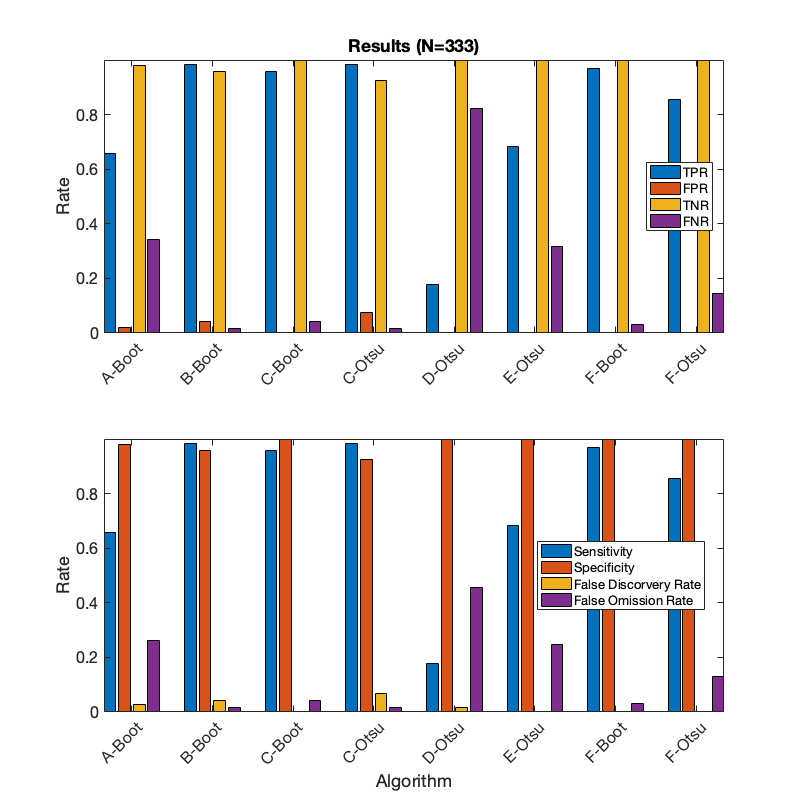

figureDetails = compileFigureDetails(16, 2, 5, 0.5, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma
C = distinguishable_colors(input.nAlgos);

fig1 = figure(1);
clf
set(fig1, 'Position', [300, 300, 800, 800])
subplot(2, 1, 1)
b = bar(results1);
xlim([0, 2])
%xticks(0:0.3:2)
axis tight
% title(sprintf('Results (N=%i)', input.nDatasets), ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title(sprintf('Results (N=%i)', input.nDatasets), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
ylabel('Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'})
xtickangle(45)
lgd = legend({'TPR', 'FPR', 'TNR', 'FNR'}, ...
    'Location', 'best');
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

subplot(2, 1, 2)
c = bar(results2);
xlim([0, 5])
%xticks(0:0.3:2)
axis tight
% title(sprintf('Results (N=%i)', input.nDatasets), ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Algorithm', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'})
xtickangle(45)
lgd = legend({'Sensitivity', 'Specificity', 'False Discorvery Rate', 'False Omission Rate'}, ...
    'Location', 'best');
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/figs/Results-%i-%i-%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets), ...
    '-djpeg')

## ROC

%% ROC
figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma
C = distinguishable_colors(input.nMethods);

fig1 = figure(1);
clf
set(set(fig1,'Position',[0, 200, 500, 500]))

%disp('Generating subplot 1 ...')
input.removeNaNs = 0;

%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

Creating Look Up Table ...
... done!



for method = 2:input.nMethods %input.nMethods %Skips Ref Q and F
    %disp(method)
    %Linear Regression
    clear Mdl
    Mdl = fitglm(predictor(:, method), response, ...
        'Distribution', 'binomial', ...
        'Link', 'logit');
    
    %Get the scores
    score_log = Mdl.Fitted.Probability;
    
    %ROC Curve coordinates
    [Xlog, Ylog, Tlog, AUClog, optOP] = perfcurve(response, score_log, 1);
    %disp(Xlog)
    %disp(Ylog)
    %disp(optOP)
    
    if isnan(Xlog)
    elseif isnan(Ylog)
        warning('Probably skipping ...')
    end
    
    if input.plotOptimalPoint
        try
            plot(optOP(1), optOP(2), 'Color', C(method, :)', 'o')
        catch
            warning('Unable to plot optimal oprational point')
        end
    end
    
    %Plots
    plot(Xlog, Ylog, '-', ...
        'Color', C(method, :), ...
        'LineWidth', figureDetails.lineWidth)
    %Add Marker Indices- to do
    title(sprintf('ROC Curves Without NaNs (N=%i)', input.nDatasets), ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold') 
    lgd1 = legend({'A (R2B)', 'B (TI)', 'C (Mean/Std)', 'D (PCA)', 'E (SVM)', 'F (Der)'}, ...
        'Location', 'best');
    lgd1.FontSize = figureDetails.fontSize;
    hold on
end

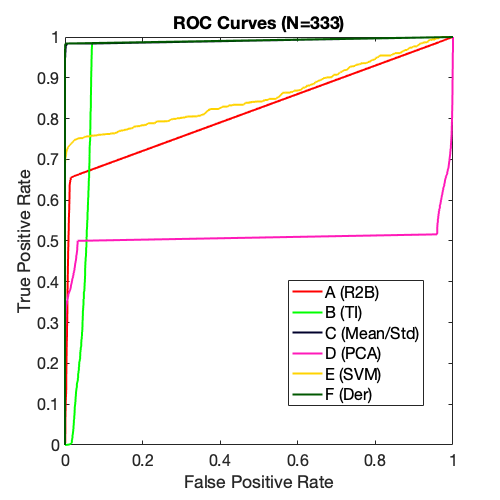

title(sprintf('ROC Curves (N=%i)', input.nDatasets), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('False Positive Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('True Positive Rate', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/figs/ROC-%i-%i-%i-%i-%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun), ...
    '-dpng')

## Plotmatrix

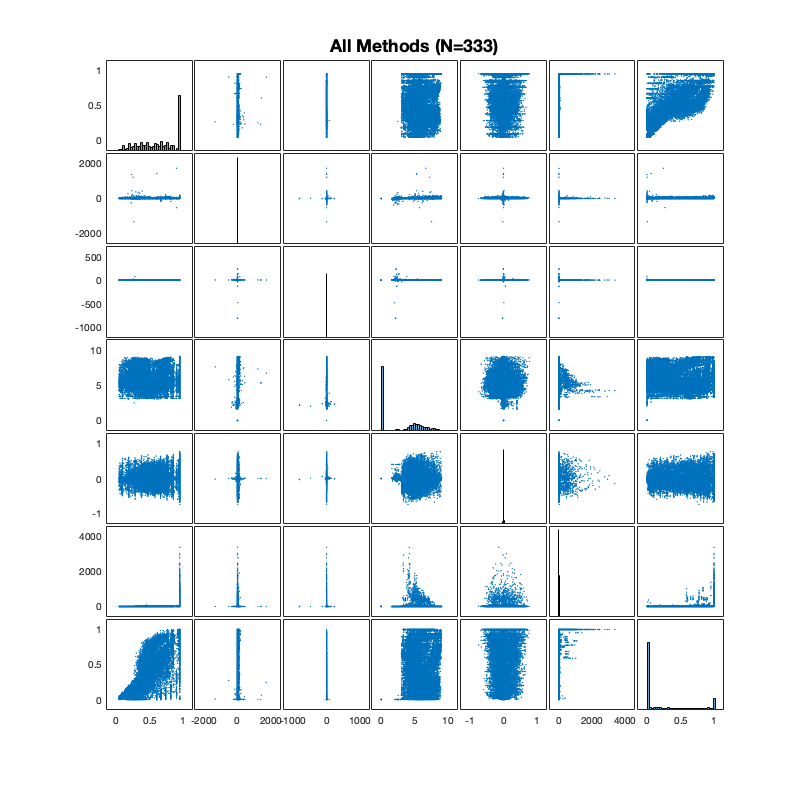

fig2 = figure(2);
set(fig2, 'Position', [300, 300, 800, 800])
plotmatrix(predictor)
title(sprintf('All Methods (N=%i)', input.nDatasets), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Methods', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
% ylabel('Methods', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/figs/plotmatrix1-%i-%i-%i-%i-%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun), ...
    '-dpng')

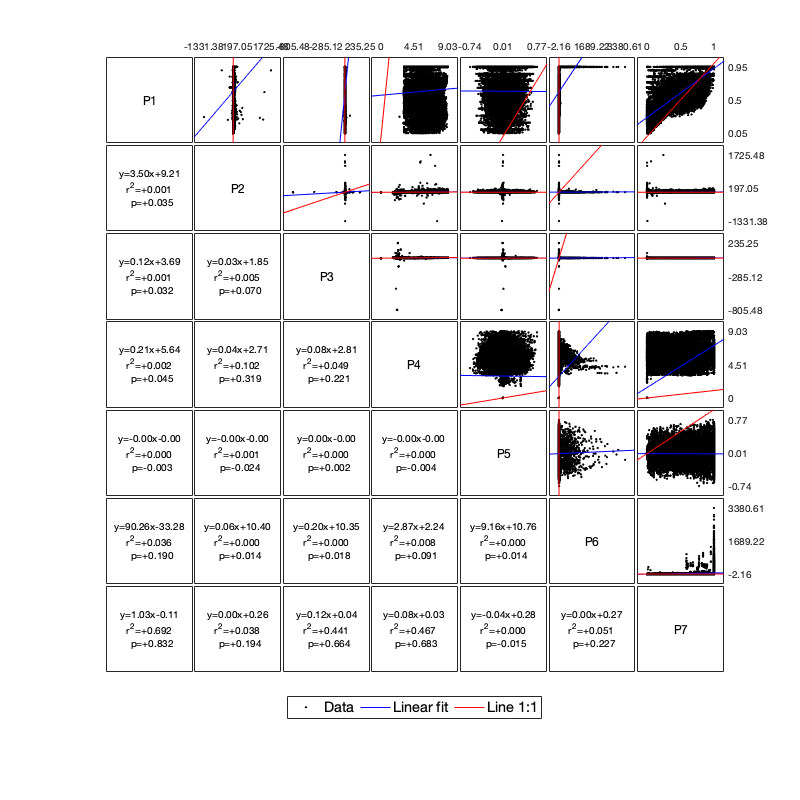


fig3 = figure(3);
set(fig3, 'Position', [300, 300, 800, 800])
plotmatrixcorr(predictor)
title(sprintf('All Methods (N=%i)', input.nDatasets), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Methods', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
% ylabel('Methods', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/figs/plotmatrix2-%i-%i-%i-%i-%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun), ...
    '-dpng')